# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant ans make diagnosis

#### Select and check the model file

file="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(3));
DiagnosisMethod='WASTE_INTERNAL';

#### Compute Diagnosis Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod,'Show',true);

Fuel Impact:     0.8000 (kW)
Malfunction Cost:     0.8000 (kW)

Diagnosis Summary

Key        MF(kW)      ΔI(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPt*(kW)
——————————————————————————————————————————————————————————————————————————————
BLR        0.3817      0.4910      0.0000      0.3817      0.5677      0.0000
TRB        0.0292     -0.0170      0.0000     -0.0594     -0.0471      0.0000
IHE       -0.0128     -0.0200      0.0000     -0.0209     -0.0043      0.0000
PMP       -0.0007     -0.0270      0.0000     -0.0011      0.0041      0.0000
CND        0.0000      0.3730      0.0000     -0.0152     -0.0055      0.0000
ENV        0.3974      0.8000      0.0000      0.2850      0.5150      0.0000


Malfunction Table (kW)

                 BLR        TRB        IHE        PMP        CND        ΔPs
————————————————————————————————————————————————————————————————————————————
 BLR          0.0000     0.1815    -0.0073     0.0000     0.0234     0.0000
 TRB          0.0000     0.0000     0

#### Show Results

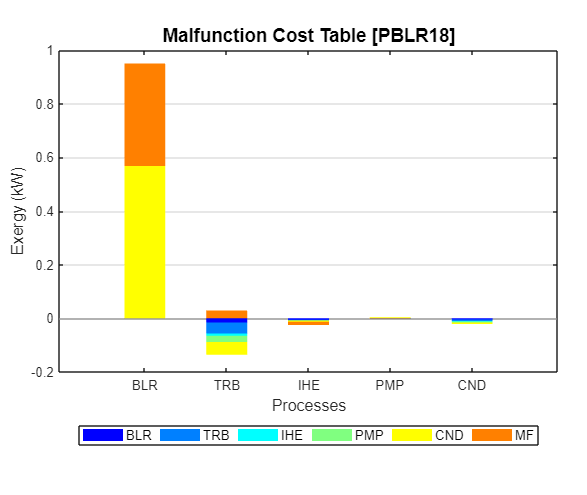

showGraph(res,'mfc',false);